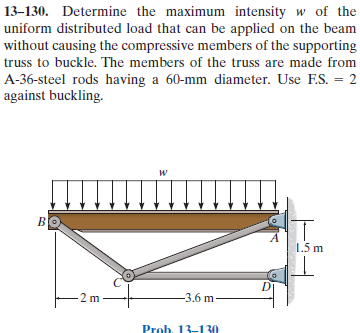

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-26P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-26P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 5.6*u.m);
b = b.add('reaction', 'force', 'Rb', 0);
b = b.add('distributed', 'force', '-wo', [0 5.6]*u.m);
b.L = 5.6*u.m;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y

$$y(x) = \frac{\mathrm{wo}\,x\,\left(5\,x-28\,m\right)\,\left(-25\,x^{2}+140\,x\,m+784\,m^{2}\right)}{3000\,\text{E}\,\text{I}}$$

dy

$$dy(x) = \frac{\mathrm{wo}\,\left(5\,x-14\,m\right)\,\left(-25\,x^{2}+140\,x\,m+392\,m^{2}\right)}{750\,\text{E}\,\text{I}}$$

m

$$m(x) = -\frac{\mathrm{wo}\,x\,\left(5\,x-28\,m\right)}{10}$$

v

$$v(x) = -\frac{\mathrm{wo}\,\left(5\,x-14\,m\right)}{5}$$

w

$$w(x) = -\mathrm{wo}$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & \frac{14\,\mathrm{wo}}{5}\,m\\ \mathrm{Rb} & \frac{14\,\mathrm{wo}}{5}\,m \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# joint data

wo_var = sym('wo', 'positive');
jointA = [0 0]*u.m;
jointB = [-5.6 0]*u.m;
jointC = [-3.6 -1.5]*u.m;
jointD = [0 -1.5]*u.m;

# member data

FS = 2;
E = 200*u.GPa;
D = 60*u.mm;
A = rewrite(sympi/4*D^2, u.m);
I = rewrite(sympi/4*(D/2)^4, u.m);
Lac = sqrt(sym(3.6)^2+sym(1.5)^2)*u.m;
Lbc = sqrt(sym(2)^2+sym(1.5)^2)*u.m;
Lcd = 3.6*u.m;
Evar = sym('E');
Avar = sym('A');

# truss

t = Truss;
t = t.add('reaction', 'Ra', {'Rax' 'Ray'}, jointA);
t = t.add('reaction', 'Rd', {'Rdx' 'Rdy'}, jointD);
t = t.add('concentrated', 'Pa', [0 rs.Ra], jointA);
t = t.add('concentrated', 'Pb', [0 rs.Rb], jointB);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('member', 'Fac', jointA, jointC, E, A);
t = t.add('member', 'Fbc', jointB, jointC, E, A);
t = t.add('member', 'Fcd', jointC, jointD, E, A);

# solution

[us ua ms ma ls la] = t.solve('factor');
A = rewrite(A, u.in);
I = rewrite(I, u.in);

# joint displacements

ua

# forces on the truss

ma_f_m = ma.f.m %#ok<NASGU> 
la_f_c = la.f.c %#ok<NASGU> 
ma_f_c = ma.f.c %#ok<NASGU> 
la_f_m = la.f.m %#ok<NASGU> 

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 
la_m_c = la.m.c %#ok<NASGU> 
ma_m_c = ma.m.c %#ok<NASGU> 
la_m_m = la.m.m %#ok<NASGU> 

# maximum load due to yield

Pcr.buckling = rewrite(sympi^2*E*I/L^2, u.kip);
Pcr_buckling = vpa(Pcr.buckling, 3) %#ok<NASGU> 
Pmax.buckling = solve(abs(ms.f.m.Fab) == Pcr.buckling/FS);
Pmax_buckling = vpa(Pmax.buckling, 3) %#ok<NASGU> 

# maximum load due to yield stress

Pcr.yield = rewrite(solve(sigma_yield == Pvar/A), u.kip);
Pcr_yield = Pcr.yield %#ok<NASGU> 
Pmax.yield = solve(abs(ms.f.m.Fab) == Pcr.yield);
Pmax_yield = vpa(Pmax.yield, 4) %#ok<NASGU> 

# clean up

clear ma_f_m la_f_c ma_f_c la_f_m;
clear ma_m_m la_m_c ma_m_c la_m_m;
clear Pcr_buckling Pmax_buckling;
clear Pcr_yield Pmax_yield;
new_assum = assumptions;